# PCA vs Fisher discriminant analysis

## Make data: Gaussian mixture in 3D

d = 3;
n1 = 200;
n2 = 300;
n = n1 + n2;
D1 = 1:n1; % indices in omega1
D2 = (n1+1):n; % indices in omega2
Sigma = [1,0.5,-1;0.5,3,1;-1,1,3];
Sinv = inv(Sigma);
mu1 = [1;1;1];
mu2 = [2;3;4];
z1 = sqrtm(Sigma)*randn(d,n1)+mu1*ones(1,n1);
z2 = sqrtm(Sigma)*randn(d,n2)+mu2*ones(1,n2);
X = [z1';z2'];

## Center data

colmean = mean(X,1);
X = X - ones(n,1)*colmean;

## Compute PCA

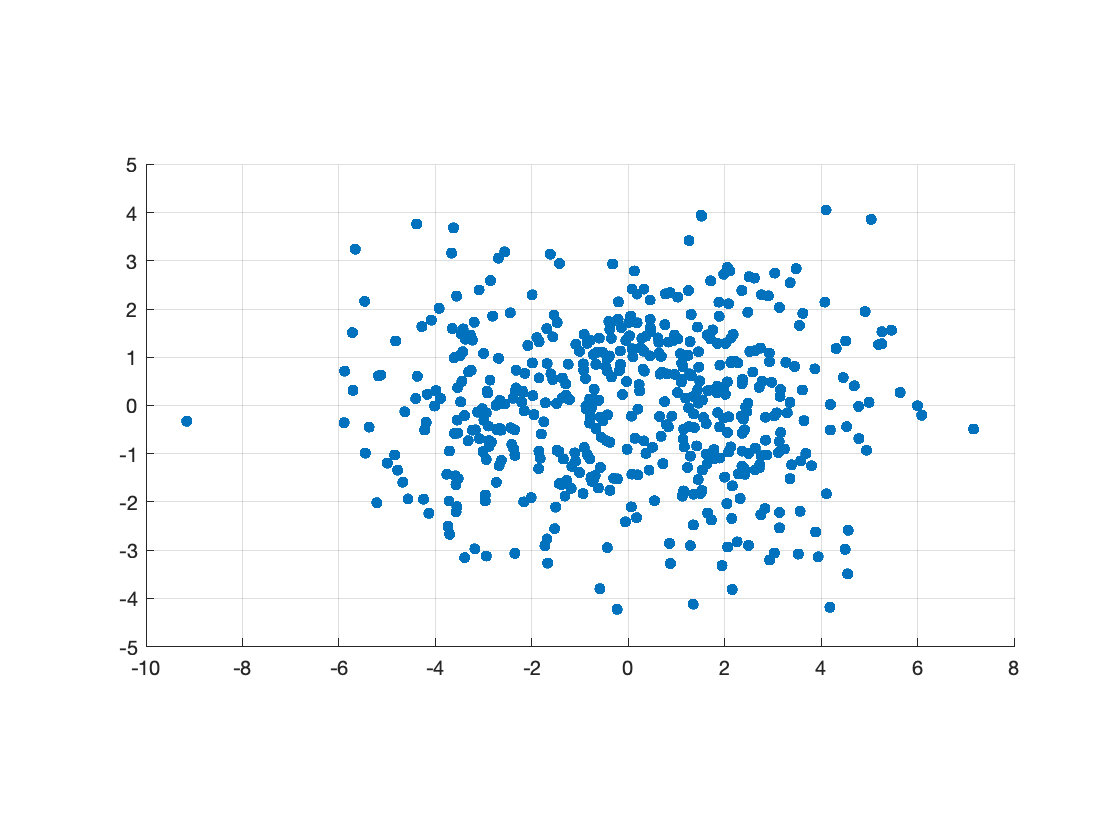

% Compute the covariance matrix
C = (1/n)*X'*X;
[W,E] = eig(C);
evals = diag(E);
[evals,isort] = sort(evals,'descend'); % sort eigenvalues
W = W(:,isort); % reindex eigenvectors accordingly
% pick eivectors corresponding to two largest eigenvalues and project the
% data on them
y1 = X*W(:,1); % PCA1
y2 = X*W(:,2); % PCA2
figure;
hold on; grid;
plot(y1,y2,'.','Markersize',15);
daspect([1,1,1])





% [U,S,W] = svd(X,'econ');
% y1 = X*W(:,1); % PCA1
% y2 = X*W(:,2); % PCA2

## Graphics

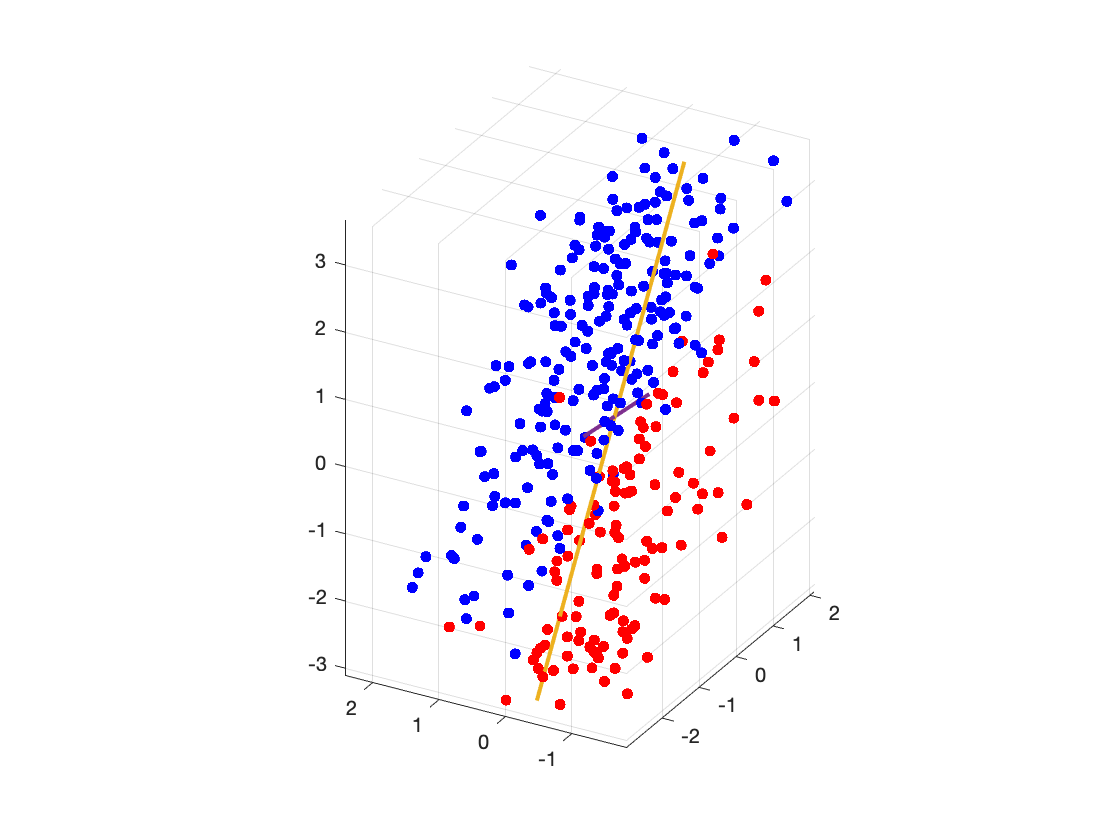

close all;
figure;
hold on; grid;
col = ['r','b'];
plot3(X(D1,1),X(D1,2),X(D1,3),'.','color',col(1),'Markersize',15);
plot3(X(D2,1),X(D2,2),X(D2,3),'.','color',col(2),'Markersize',15);
view(3);
t = linspace(-8,8,100);
l1 = W(:,1)*t;
l2 = W(:,2)*t;
plot3(l1(1,:),l1(2,:),l1(3,:),'Linewidth',2);
plot3(l2(1,:),l2(2,:),l2(3,:),'Linewidth',2);
daspect([1,1,1])

## Map to 1D

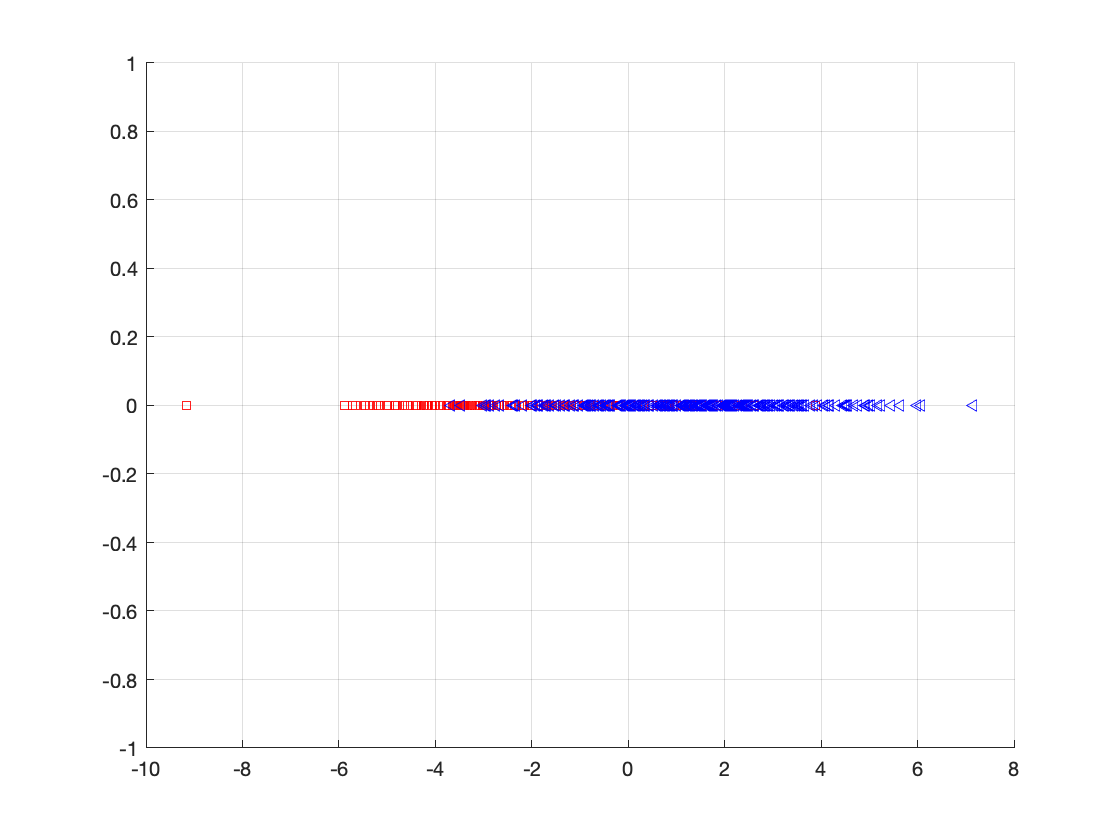

figure;
hold on; grid;
plot(y1(D1),zeros(n1,1),'s','color','none',...
    'Markeredgecolor',col(1),'Markersize',5);
plot(y1(D2,1),zeros(n2,1),'<','color','none',...
    'Markeredgecolor',col(2),'Markersize',5);

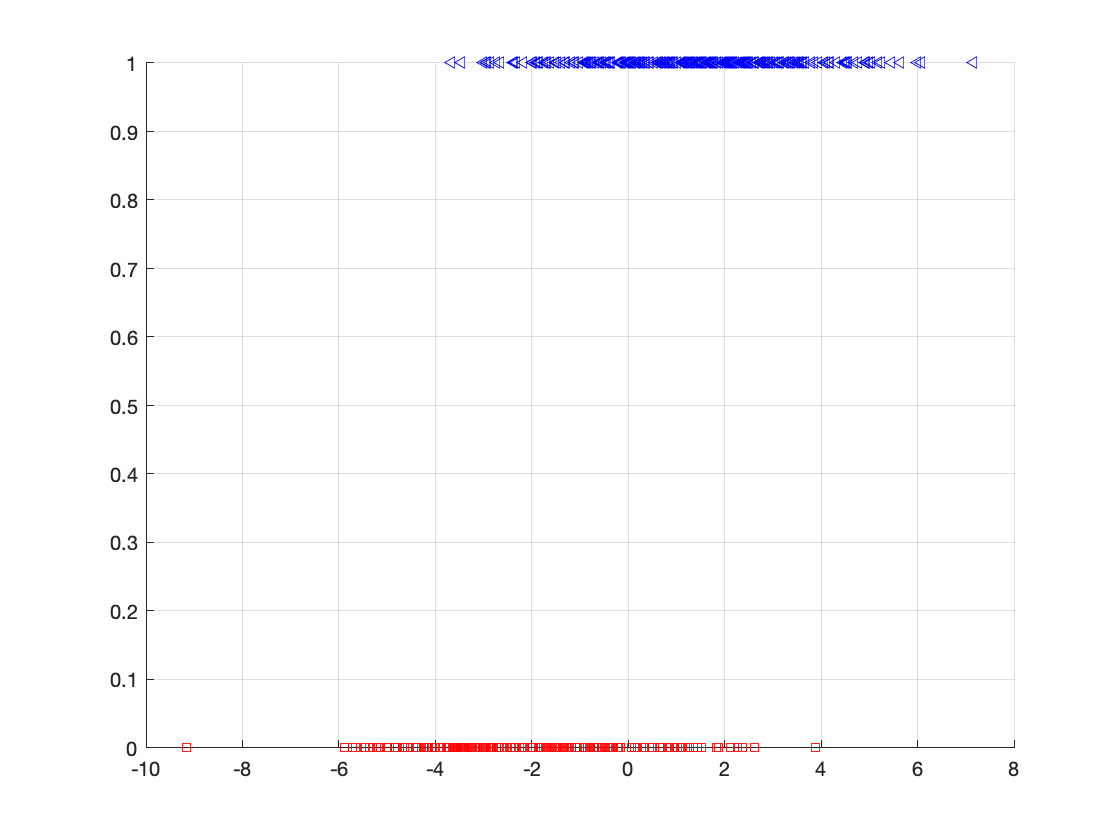

figure;
hold on; grid;
plot(y1(D1),zeros(n1,1),'s','color','none',...
    'Markeredgecolor',col(1),'Markersize',5);
plot(y1(D2,1),ones(n2,1),'<','color','none',...
    'Markeredgecolor',col(2),'Markersize',5);

## Map to 2D

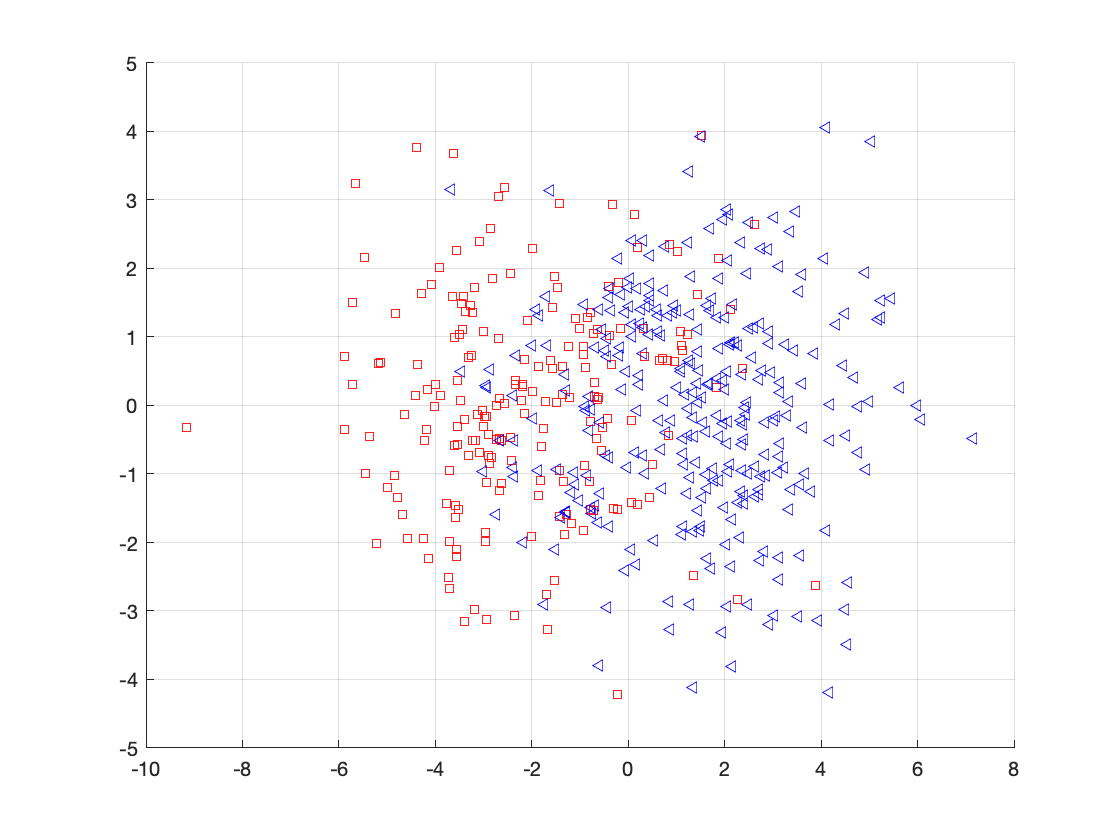

figure;
hold on; grid;
plot(y1(D1),y2(D1),'s','color','none',...
    'Markeredgecolor',col(1),'Markersize',5);
plot(y1(D2),y2(D2),'<','color','none',...
    'Markeredgecolor',col(2),'Markersize',5)

## Fisher linear discriminant analysis

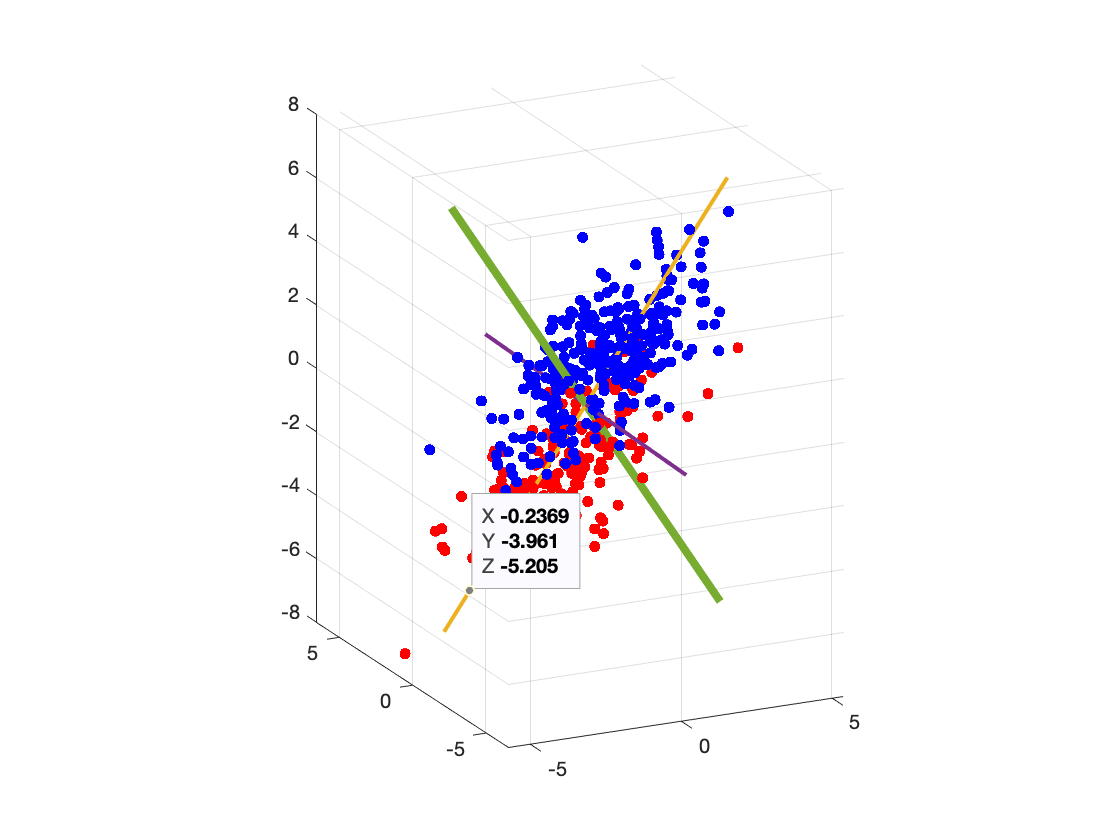

% compute within-class scatter Sw
m1 = mean(X(D1,:),1);
m2 = mean(X(D2,:),1);
X1 = X(D1,:);
X2 = X(D2,:);
Xc1 = X1-ones(n1,1)*m1;
S1 = Xc1'*Xc1;
Xc2 = X2-ones(n2,1)*m2;
S2 = Xc2'*Xc2;
Sw = S1+S2;
w = Sw\(m1-m2)';
w = w/norm(w); % normalize (unnecessary)
% graphics
figure;
hold on; grid;
plot3(X(D1,1),X(D1,2),X(D1,3),'.','color',col(1),'Markersize',15);
plot3(X(D2,1),X(D2,2),X(D2,3),'.','color',col(2),'Markersize',15);
view(3);
t = linspace(-8,8,100);
l1 = W(:,1)*t;
l2 = W(:,2)*t;
f = w*t;
plot3(l1(1,:),l1(2,:),l1(3,:),'Linewidth',2);
plot3(l2(1,:),l2(2,:),l2(3,:),'Linewidth',2);
plot3(f(1,:),f(2,:),f(3,:),'Linewidth',4);
daspect([1,1,1])

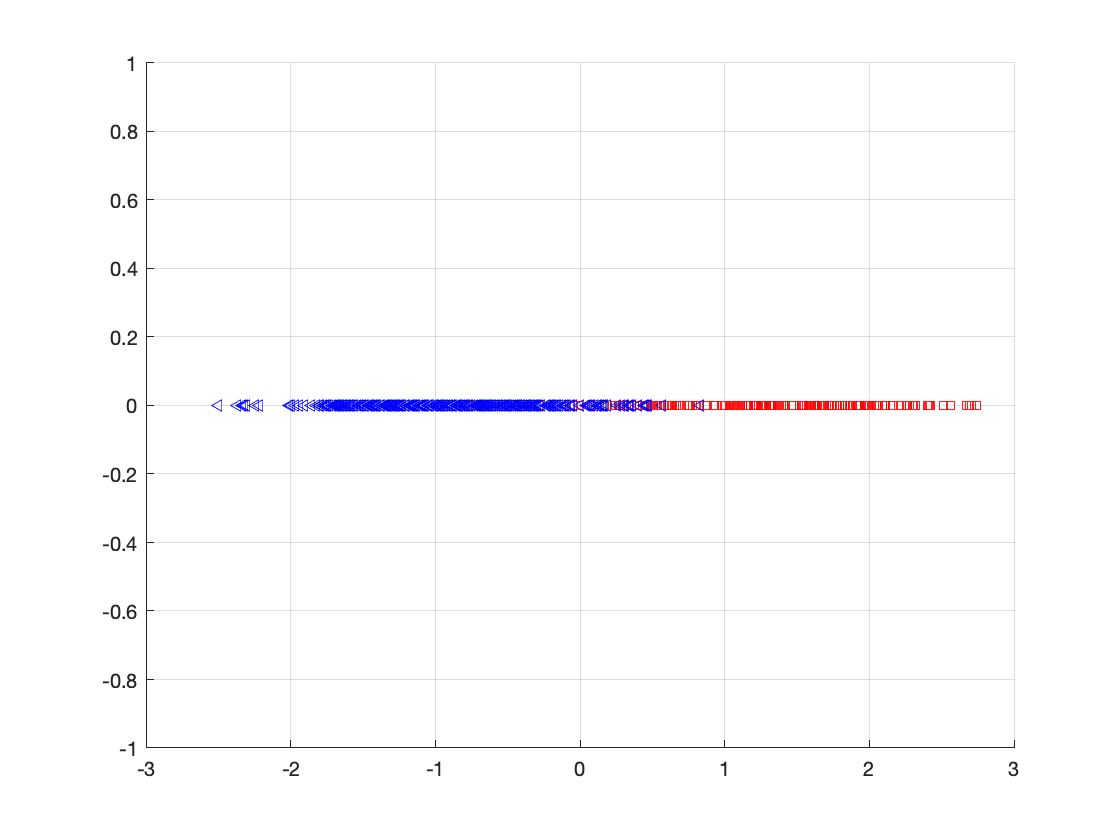

% map to 1D
figure;
hold on; grid;
y = X*w;
plot(y(D1),zeros(n1,1),'s','color','none',...
    'Markeredgecolor',col(1),'Markersize',5);
plot(y(D2,1),zeros(n2,1),'<','color','none',...
    'Markeredgecolor',col(2),'Markersize',5);

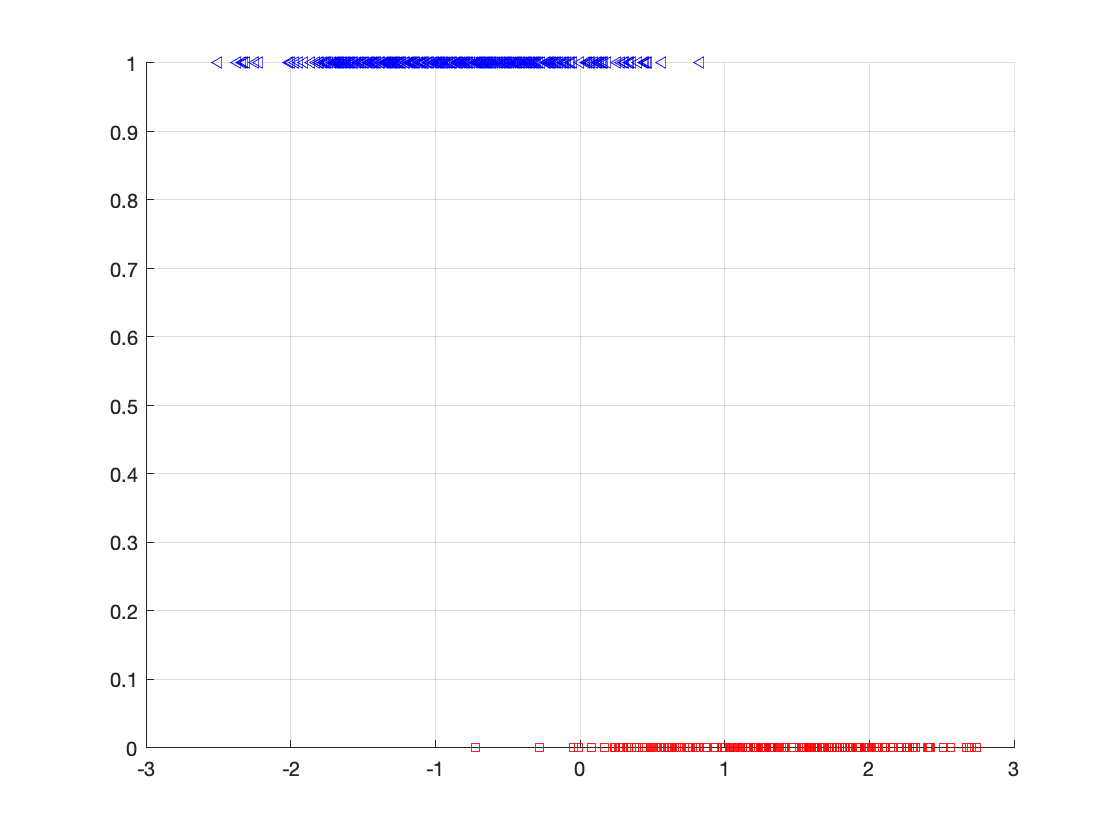

figure;
hold on; grid;
plot(y(D1),zeros(n1,1),'s','color','none',...
    'Markeredgecolor',col(1),'Markersize',5);
plot(y(D2,1),ones(n2,1),'<','color','none',...
    'Markeredgecolor',col(2),'Markersize',5);